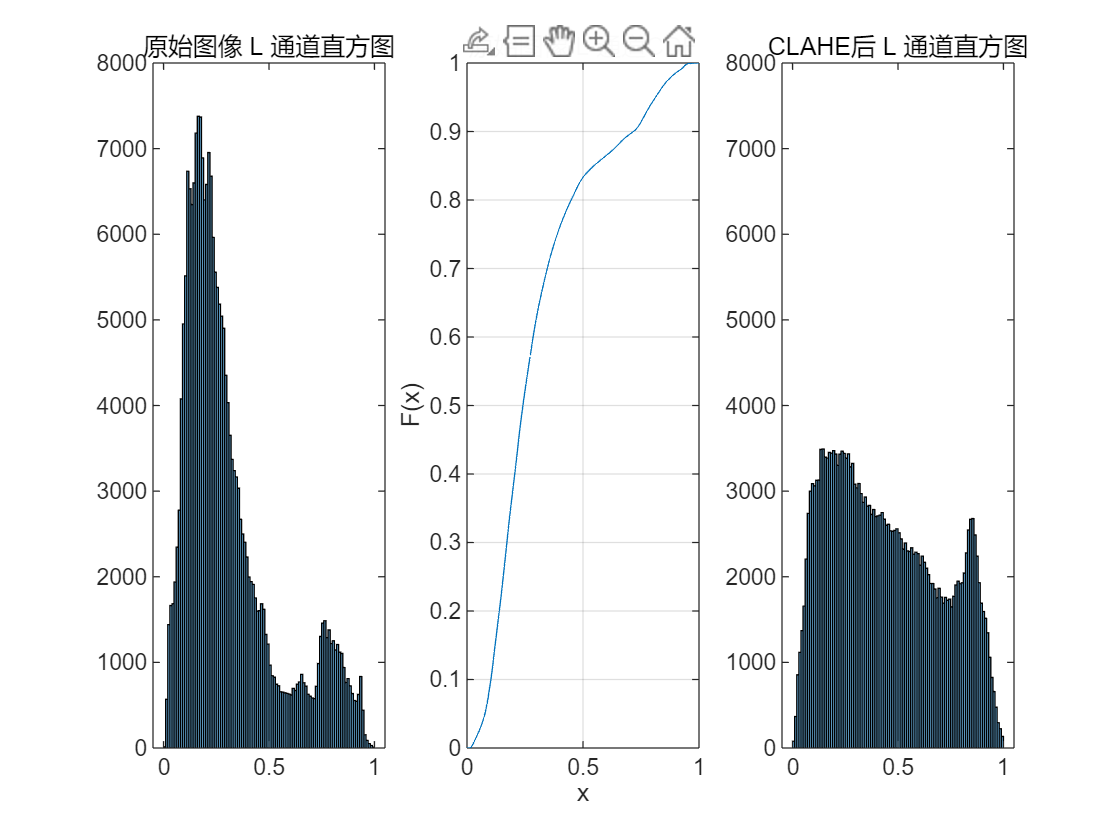

clc; clear; close all;

% 读入 RGB 图像
rgbImage = imread('2.jpg');

% 转换到 Lab 空间
labImage = rgb2lab(rgbImage);

% ---------- L 通道做 CLAHE ----------
L = labImage(:,:,1);
Lnorm = mat2gray(L);  

Lclahe = adapthisteq(Lnorm);

figure;
subplot(1,3,1);
histogram(Lnorm), title('原始图像 L 通道直方图');
subplot(1,3,3);
histogram(Lclahe), title('CLAHE后 L 通道直方图'), ylim([0 8000]);
subplot(1,3,2);
cdfplot(Lnorm(:)), title('原始图像 L 通道CDF');

labImage(:,:,1) = Lclahe * 100;   % CLAHE 后缩放回 [0,100]
L_orgin = lab2rgb(labImage);
imwrite(L_orgin, 'out1.jpg');

% ---------- a、b 通道做白平衡 ----------
a = labImage(:,:,2);
b = labImage(:,:,3);

% 计算均值偏移量
aMean = mean(a(:));
bMean = mean(b(:));

% 将均值校正到 0
aWB = a - aMean;
bWB = b - bMean;

labImage(:,:,2) = aWB;
labImage(:,:,3) = bWB;

% ---------- 转换回 RGB ----------
rgbEnhanced = lab2rgb(labImage);
imwrite(rgbEnhanced, 'out2.jpg');

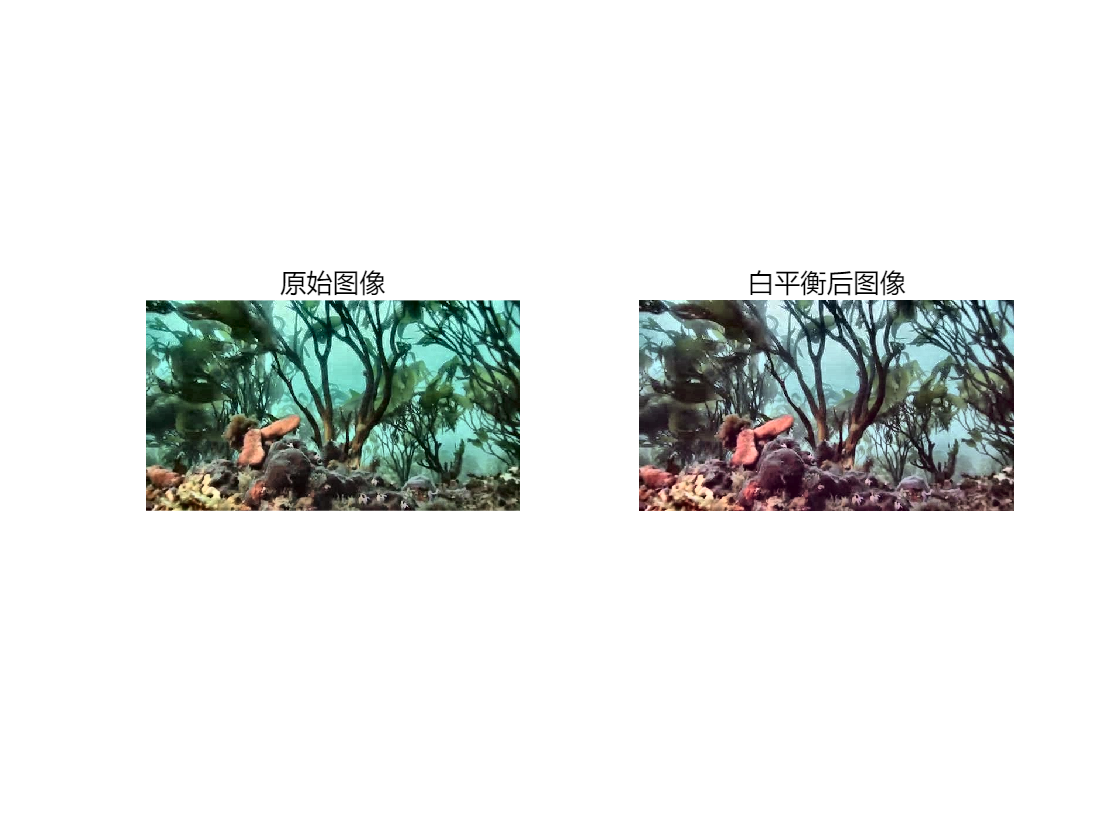

%% 1. 读取图像
I = L_orgin; % 示例图
I_balanced = rgbEnhanced; 
% 用 MATLAB 自带的白平衡函数 chromadapt 模拟，参数可改

%% 2. 原图 vs 白平衡图
figure;
subplot(1,2,1), imshow(I), title('原始图像');
subplot(1,2,2), imshow(I_balanced), title('白平衡后图像');

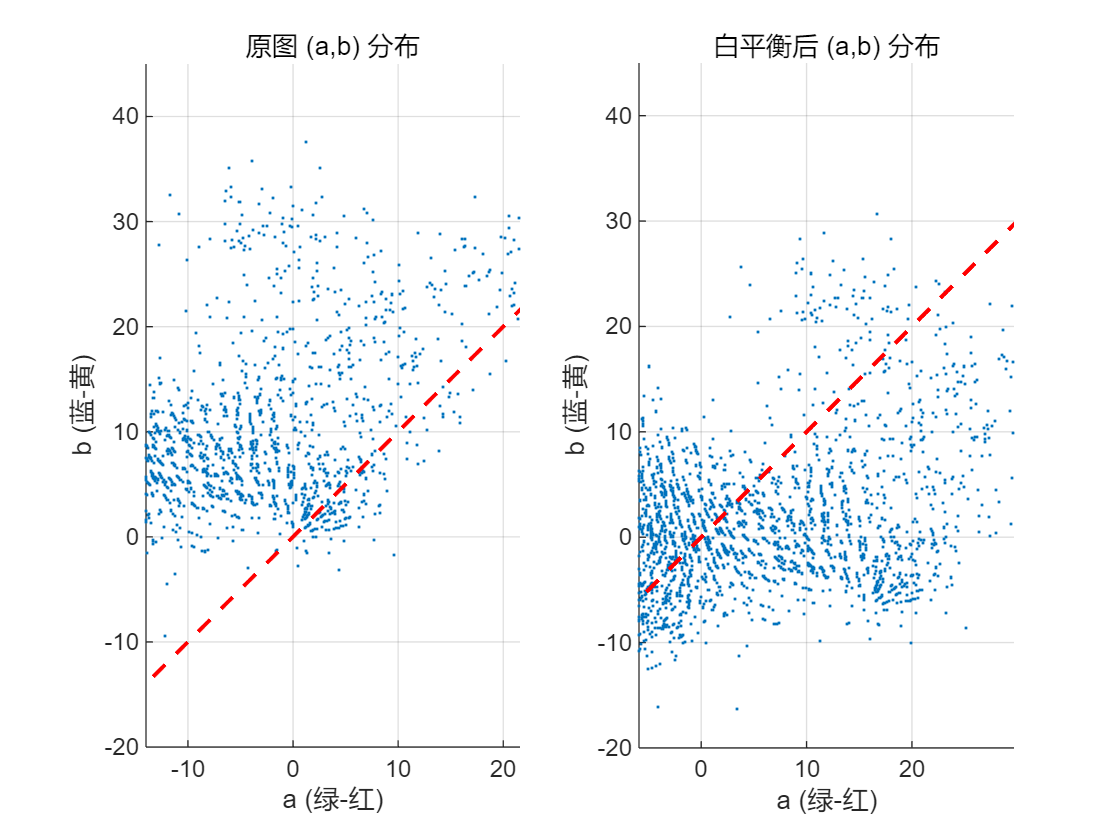

%% 3. 转换到 Lab 空间
lab_orig = rgb2lab(I);
lab_bal  = rgb2lab(I_balanced);

a_orig = lab_orig(:,:,2);
b_orig = lab_orig(:,:,3);
a_bal  = lab_bal(:,:,2);
b_bal  = lab_bal(:,:,3);

% 随机抽样部分像素以避免点太多
sample_idx = randperm(numel(a_orig), 5000);
a_orig_s = a_orig(sample_idx);
b_orig_s = b_orig(sample_idx);
a_bal_s  = a_bal(sample_idx);
b_bal_s  = b_bal(sample_idx);

x = -50:0.1:50;

% 绘制 (a,b) 平面分布
figure;
subplot(1,2,1);
scatter(a_orig_s, b_orig_s, 5, '.'); 
xlabel('a (绿-红)'), ylabel('b (蓝-黄)');
title('原图 (a,b) 分布');
axis equal; grid on;
ylim([-20 45]);
hold on;             % 保持图像，不覆盖
plot(x,x,'r--','LineWidth',1.5); % y=x，红色虚线
hold off;

subplot(1,2,2);
scatter(a_bal_s, b_bal_s, 5, '.'); 
xlabel('a (绿-红)'), ylabel('b (蓝-黄)');
title('白平衡后 (a,b) 分布');
axis equal; grid on;
ylim([-20 45]);
hold on;             % 保持图像，不覆盖
plot(x,x,'r--','LineWidth',1.5); % y=x，红色虚线
hold off;

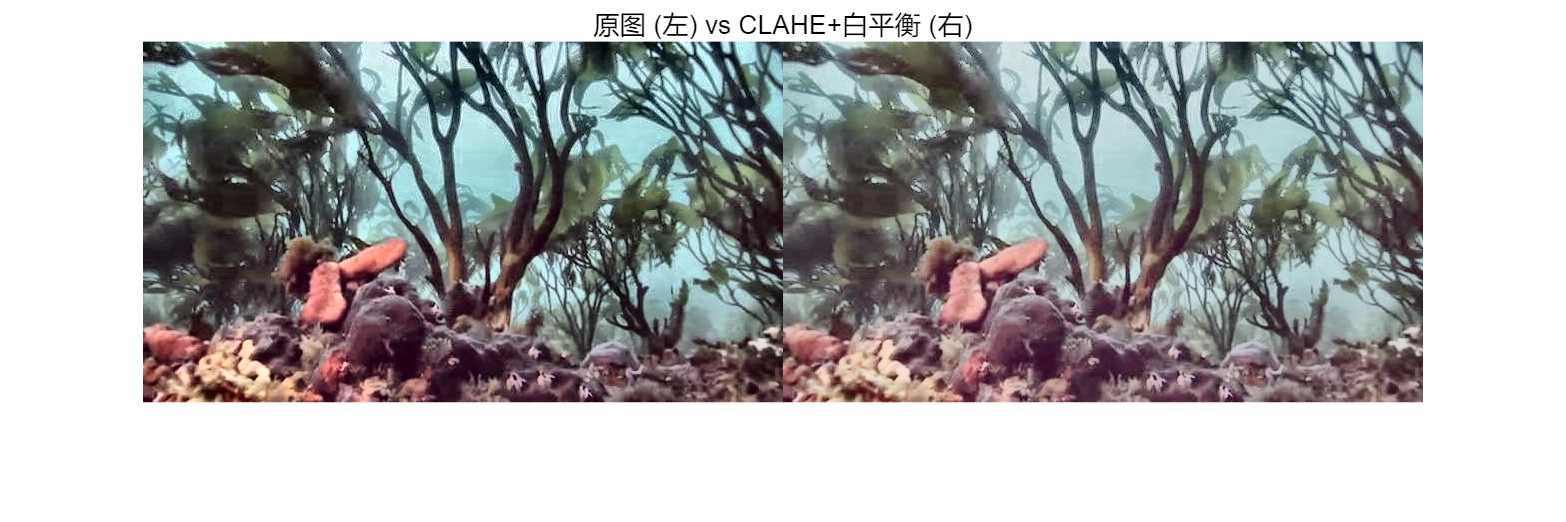

% 1. 读取图像
I = rgbEnhanced;
I = im2double(I);   % [0,1] 范围

% 2. 转灰度
% I_gray = I;
x = I;

% 3. 标准正态分布 PDF 变换
s1 = ((1 ./ sqrt(2 * pi)) .* (exp(- .5 .* (x.^2))));
imwrite(s1, 'out3.jpg');
% 4. Softplus 变换
s2 = (log(1 + exp(x)));
imwrite(s2, 'out4.jpg');
% 5. 对数合并（相乘 + 相加，再开方）
s = sqrt((s1 + s2) + (s1 .* s2));

% 6. 归一化 + 伽马矫正
gamma = 1;
out = ((s - min(s(:))) ./ (max(s(:)) - min(s(:)))).^gamma;
imwrite(out, 'out5.jpg');

figure;
imshowpair(rgbEnhanced, out, 'montage');
title('原图 (左) vs CLAHE+白平衡 (右)');